This File will plot the metrics HammingDistance and SuccesProbability

For different Measurments amount M.

CASES = 100; % amount of elements sparse vector
AmountOfSamples = 500;
NoiseParameter = 0.00; % will be zero
k=10; % amount of defectives sparse vector

%Algorithms will run for multiple samples to give a good average
% performance. Parameters for given dataset are CASES =100, k=10
% and AmountOfSamples = 1000
x = MakeSparseMatrix(CASES,AmountOfSamples,k);

% These parameters can be changed to make the code run faster
Mrange = 10:5:CASES; 
iterations =300; 

% Initializing plot arrays. If no name is given it is DD algorithm
xMeasurment = zeros(length(Mrange),1);
yplot = zeros(length(Mrange),1);
yplot_lin_prog  = yplot;


yplot_COMP  = yplot;
yplot_SCOMP  = yplot;



ySplot = yplot;
ySplot_lin_prog  = yplot;
ySplot_COMP  = yplot;
ySplot_SCOMP  = yplot;

% formula used for Bernouli design
p = (1/(k+1));


plotindex = 1;

%Outerloop will run for each M, innerloop will do it multiple times
% to achieve a good average performance
for M = Mrange  
    A_example = generateA(p, M, CASES); %Bernouli Design
    disp(M)
    sum = 0;
    sum_lin_prog = 0;
    sum_COMP = 0;
    sum_SCOMP = 0;


    sumS = 0;
    sumS_lin_prog = 0;
    sumS_COMP = 0;
    sumS_SCOMP = 0;
    for i = 1:iterations
        x_groundTruth = x(:,i); %take a sample
        
        
        Noise = rand(M, 1) < NoiseParameter;
        

        y = double(xor(sign(A_example*x_groundTruth),double(Noise))); % generate y
        
        [x_output] = calcDD(A_example,y, CASES); %DD
        [hamming_distance] = calcHammingDist(x_groundTruth, x_output');
        [resultSucess] = IsSuccesfull(x_groundTruth, x_output');
        
        [x_output_linear_prog,Z] = LPrelax(A_example,y); % LPrelaxAlgoritm
        [hamming_dstance_linear_prog] = calcHammingDist(x_groundTruth, x_output_linear_prog);
        [resultSucess_linear_prog] = IsSuccesfull(x_groundTruth, x_output_linear_prog);

        [x_output_COMP] = calcCOMP(A_example,y,CASES); % COMP
        [hamming_dstance_COMP] = calcHammingDist(x_groundTruth, x_output_COMP');
        [resultSucess_COMP] = IsSuccesfull(x_groundTruth, x_output_COMP');


        [x_output_SCOMP] = calcSeqCOMP(A_example, y, CASES); % SCOMP
        [hamming_dstance_SCOMP] = calcHammingDist(x_groundTruth, x_output_SCOMP');
        [resultSucess_SCOMP] = IsSuccesfull(x_groundTruth, x_output_SCOMP');
        
        %Summing performance metrics to calculate averages.
        sum = sum + hamming_distance;
        sum_lin_prog = sum_lin_prog + hamming_dstance_linear_prog;
        sum_COMP = sum_COMP + hamming_dstance_COMP;
        sum_SCOMP = sum_SCOMP + hamming_dstance_SCOMP;


        sumS = sumS + resultSucess;
        sumS_lin_prog = sumS_lin_prog + resultSucess_linear_prog;
        sumS_COMP = sumS_COMP + resultSucess_COMP;
        sumS_SCOMP = sumS_SCOMP + resultSucess_SCOMP;

        
    end
    
    % Calculation the average performance for each M
    xMeasurment(plotindex) = M;
     
    yplot(plotindex) = sum/iterations;
    yplot_lin_prog(plotindex) = sum_lin_prog/iterations;    
    yplot_COMP(plotindex) = sum_COMP/iterations;
    yplot_SCOMP(plotindex) = sum_SCOMP/iterations;


    ySplot(plotindex) = sumS/iterations;
    ySplot_lin_prog(plotindex) = sumS_lin_prog/iterations;
    ySplot_COMP(plotindex) = sumS_COMP/iterations;
    ySplot_SCOMP(plotindex) = sumS_SCOMP/iterations;

    plotindex = plotindex+1;

end

    10

    15

    20

    25

    30

    35

    40

    45

    50

    55

    60

    65

    70

    75

    80

    85

    90

    95

   100



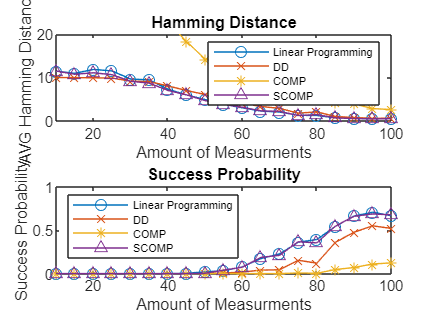

% Creation of the Figure.
figure;

% Plot the first subplot
subplot(2, 1, 1);
plot(xMeasurment, yplot_lin_prog,"o-");
hold on;
plot(xMeasurment, yplot,"x-");
plot(xMeasurment, yplot_COMP,"*-");
plot(xMeasurment, yplot_SCOMP,"^-");
xlabel("Amount of Measurments");
ylabel("AVG Hamming Distance");
ylim([0,20]);
title('Hamming Distance');
xlim([10,100]);
hLegend = legend('Linear Programming', 'DD', 'COMP', 'SCOMP', 'Location', 'northeast');
set(hLegend, 'FontSize', 6); % Adjust the font size of the legend

% Plot the second subplot
subplot(2, 1, 2);
plot(xMeasurment, ySplot_lin_prog,"o-");
hold on;
plot(xMeasurment, ySplot,"x-");
plot(xMeasurment, ySplot_COMP,"*-");
plot(xMeasurment, ySplot_SCOMP,"^-");
xlabel("Amount of Measurments");
ylabel("Success Probability");
ylim([0,1]);
xlim([10,100]);
title('Success Probability');

% Create a common legend for both subplots
hLegend = legend('Linear Programming', 'DD', 'COMP', 'SCOMP', 'Location', 'northwest');
set(hLegend, 'FontSize', 6); % Adjust the font size of the legend


%saveas(gcf, 'Measurment.png', 'png');

